# Pendolo Invertito

Iniziamo settando i parametri del sistema ad alcuni valori iniziali:

clear;
clearvars;
%x,t,m,M,l,F
dt = (0:0.05:20);
m = 0.1;%kg
M = 1;%kg
l = 0.5;%m
F = 1;%N
g = 9.81; %m/s^2

Infine le condizioni iniziali e la precisione del risolutore:

x0 = [pi/5,0,0,0];% theta_0 = 0, velocità angolare = 0 posizione iniziale=0
% velocità iniziale 0 m/s
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

Chiamiamo ora il nostro ode45:

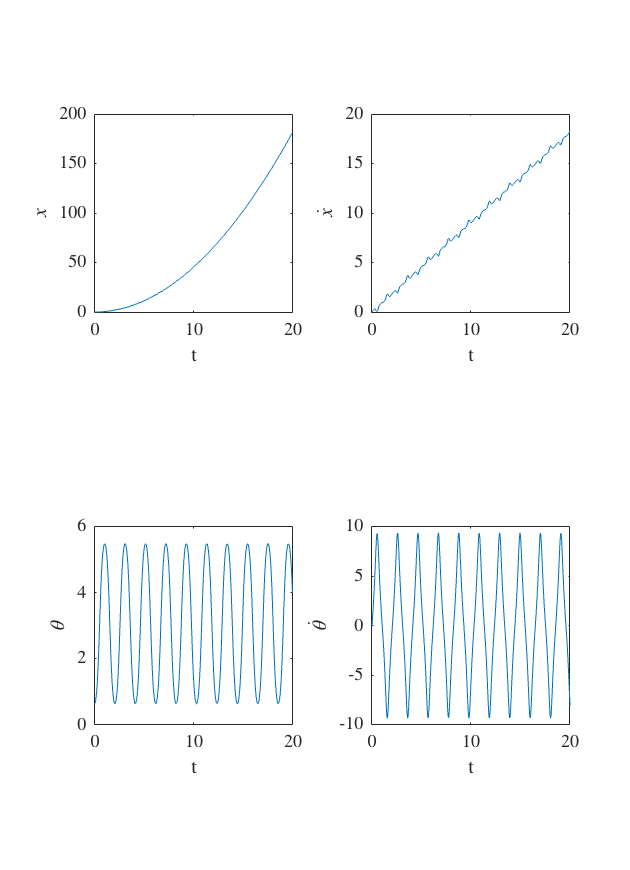

[t,x] = ode45(@(t,x)Inv_pend(x,t,m,M,l,F),dt,x0,opts);
prima_ris = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
subplot(2,2,1)
plot(t,x(:,3))
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$x$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
subplot(2,2,2);
plot(t,x(:,4))
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\dot{x}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
subplot(2,2,3);
plot(t,x(:,1));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\theta$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
subplot(2,2,4);
plot(t,x(:,2));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

%exportgraphics(prima_ris,'prima_ris.eps','Resolution',300);

Andiamo ora a fare uno studio parametrico del nostro sistema:

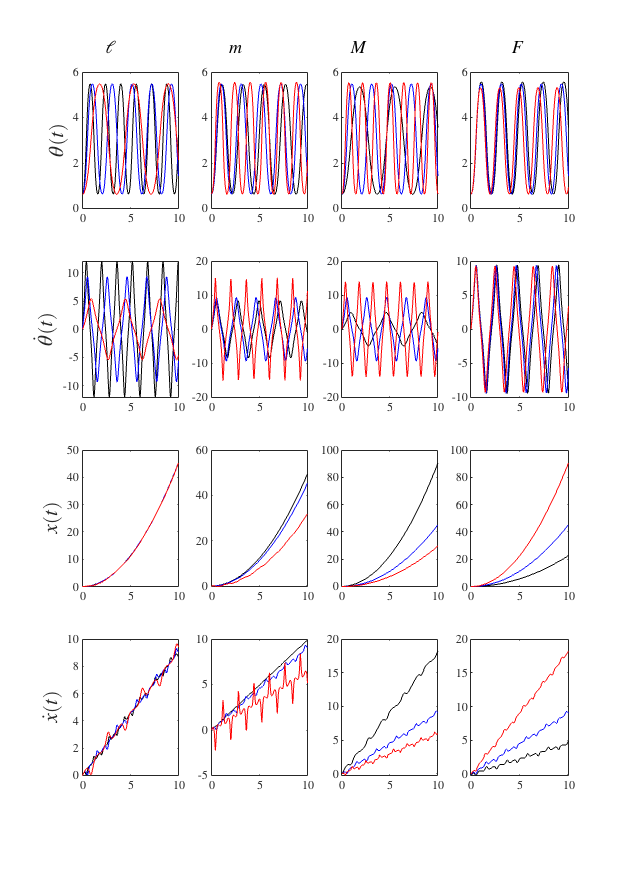

dt = (0:0.05:10);
C = {'k','b','r'}; % Cell array of colros.
studio_param = figure;
sgtitle('$\ell \quad\quad\quad\quad\quad\quad \;  m \quad\quad\quad\quad\quad\quad M \quad\quad\quad\quad\quad\quad\quad\quad  F$','Interpreter','latex');
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
k = 1;
for i= 1:4
    % i varia tra le gradezze da riportare
    

    if (i ~= 1)
        k = 4*(i-1)+1;
    end
    index = i-1;
    while k<=4*index+4
       
        %l
        l_val = [0.3 0.5 1.5];
        subplot(4,4,k);
        for j = 1:length(l_val)
        [t,x_j] = ode45(@(t,x)Inv_pend(x,t,m,M,l_val(j),F),dt,x0,opts);
        [x_pulito,b] =  rmoutliers(x_j(:,i)); %a ripulito b vettore logico
        %t_pulito ha le dimensioni di a
        t_pulito = t(~b) ;
        plot(t_pulito,x_pulito,'color',C{j});
        set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
            if j ==1
                hold on;
            end
        end
            %Ylabel 
            if k == 1
                ylabel ('$\theta(t)$','Interpreter','latex','FontSize',14);
            end
            if k == 5
                ylabel ('$\dot{\theta}(t)$','Interpreter','latex','FontSize',14);
            end
             if k == 9
                ylabel ('$x(t)$','Interpreter','latex','FontSize',14);
            end
             if k == 13
                ylabel ('$\dot{x}(t)$','Interpreter','latex','FontSize',14);
             end
            k = k+1;

        %m
        m_val = [0.01 0.1 0.5];
        subplot(4,4,k);
        for j = 1:length(m_val)
        [t,x_j] = ode45(@(t,x)Inv_pend(x,t,m_val(j),M,l,F),dt,x0,opts);
        [x_pulito,b] =  rmoutliers(x_j(:,i)); %a ripulito b vettore logico
        %t_pulito ha le dimensioni di a
        t_pulito = t(~b) ;
        plot(t_pulito,x_pulito,'color',C{j});
        set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
            if j ==1
                hold on;
            end
        end
        k = k+1;

        %M
        M_val = [0.5 1 1.5];
        subplot(4,4,k);
        for j = 1:length(M_val)
        [t,x_j] = ode45(@(t,x)Inv_pend(x,t,m,M_val(j),l,F),dt,x0,opts);
        [x_pulito,b] =  rmoutliers(x_j(:,i)); %a ripulito b vettore logico
        %t_pulito ha le dimensioni di a
        t_pulito = t(~b) ;
        plot(t_pulito,x_pulito,'color',C{j});
        set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
            if j ==1
                hold on;
            end
        end
        k = k+1;

        %F
        F_val = [0.5 1 2];
        subplot(4,4,k);
        for j = 1:length(F_val)
        [t,x_j] = ode45(@(t,x)Inv_pend(x,t,m,M,l,F_val(j)),dt,x0,opts);
        [x_pulito,b] =  rmoutliers(x_j(:,i)); %a ripulito b vettore logico
        %t_pulito ha le dimensioni di a
        t_pulito = t(~b) ;
        plot(t_pulito,x_pulito,'color',C{j});
        set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
            if j ==1
                hold on;
            end
        end
          k = k+1;
    end
    
end

%exportgraphics(studio_param,'studio_param.eps','Resolution',300);

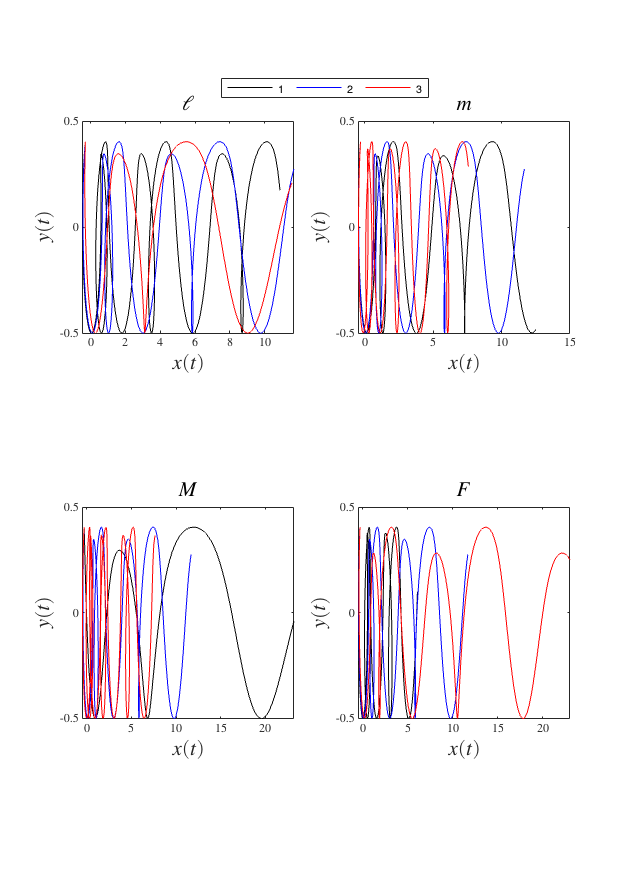

dt = (0:0.001:5);
studio_param_cart = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
t = tiledlayout(2,2);%,'Padding','none');
t.TileSpacing = 'compact';
    %l
    nexttile;
    for k = 1:3
       [t,x] = ode45(@(t,x)Inv_pend(x,t,m,M,l_val(k),F),dt,x0,opts);
        xc = x(:,3); %x carrello
        thetam = x(:,1); %theta 
        xm = xc-l*sin(thetam);
        ym = l*cos(thetam);
        plot(xm,ym,'color', C{k});
        if (k == 1)
            hold on;
        end
        set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
        title('$\ell$', 'Interpreter','latex','FontSize',14);
        xlabel('$x(t)$','Interpreter','latex','FontSize',14);
        ylabel('$y(t)$','Interpreter','latex','FontSize',14);
        axis square;
    end
    i = i+1;
    
    %m
    nexttile;
    for k = 1:3
        [t,x] = ode45(@(t,x)Inv_pend(x,t,m_val(k),M,l,F),dt,x0,opts);   
        xc = x(:,3); %x carrello
        thetam = x(:,1); %theta 
        xm = xc-l*sin(thetam);
        ym = l*cos(thetam);
        plot(xm,ym,'color', C{k});
        if (k == 1)
            hold on;
        end
        set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
        title('$m$', 'Interpreter','latex','FontSize',14);
        xlabel('$x(t)$','Interpreter','latex','FontSize',14);
        ylabel('$y(t)$','Interpreter','latex','FontSize',14);
        axis square;
    end
    i = i+1;
    
    %M
    nexttile;
    for k = 1:3
        [t,x] = ode45(@(t,x)Inv_pend(x,t,m,M_val(k),l,F),dt,x0,opts);
        xc = x(:,3); %x carrello
        thetam = x(:,1); %theta 
        xm = xc-l*sin(thetam);
        ym = l*cos(thetam);
        plot(xm,ym,'color', C{k});
        if (k == 1)
            hold on;
        end
        set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
        title('$M$', 'Interpreter','latex','FontSize',14);
        xlabel('$x(t)$','Interpreter','latex','FontSize',14);
        ylabel('$y(t)$','Interpreter','latex','FontSize',14);
        axis square;
    end
    i = i+1;

    nexttile;
    %F
    for k = 1:3
        [t,x] = ode45(@(t,x)Inv_pend(x,t,m,M,l,F_val(k)),dt,x0,opts);
        xc = x(:,3); %x carrello
        thetam = x(:,1); %theta 
        xm = xc-l*sin(thetam);
        ym = l*cos(thetam);
        plot(xm,ym,'color', C{k});
        if (k == 1)
            hold on;
        end
        set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
        title('$F$', 'Interpreter','latex','FontSize',14);
        xlabel('$x(t)$','Interpreter','latex','FontSize',14);
        ylabel('$y(t)$','Interpreter','latex','FontSize',14);
        axis square;
        
    end
    leg = legend('1','2','3','Orientation', 'Horizontal');
    leg.Layout.Tile = 'north';

    %exportgraphics(studio_param_cart,'studio_param_cart.eps','Resolution',300);


Traiettoria nel piano cartesiano:

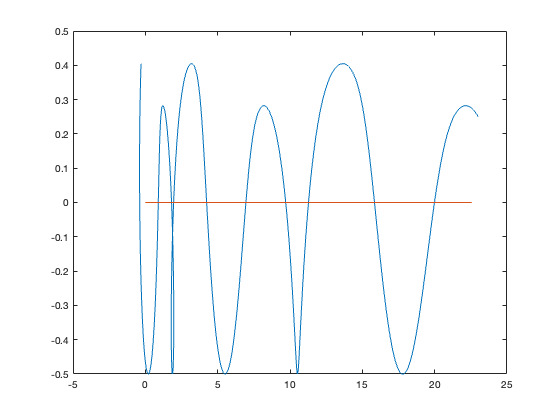

xc = x(:,3); %x carrello
yc = zeros(size(xc,1),1);
thetam = x(:,1);
xm = xc-l*sin(thetam);
ym = l*cos(thetam);
figure;
plot(xm,ym);
hold on;
plot(xc,yc);

Studio nello spazio delle fasi:

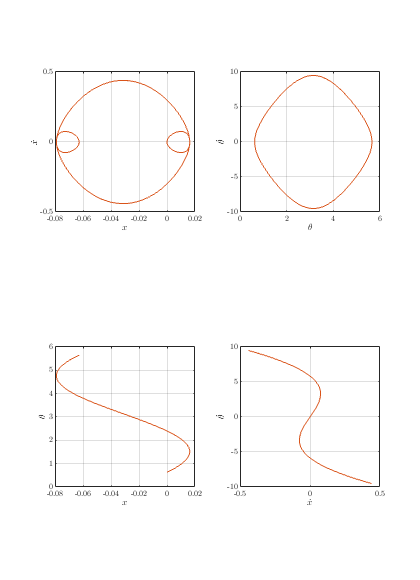

dt = [0 20];
m = 0.1;%kg
M = 1;%kg
l = 0.5;%m
F = 0;%N
x0 =[pi/5,0,0,0];
[t,x] = ode45(@(t,x)Inv_pend(x,t,m,M,l,F),dt,x0,opts);
studio_piano_fasi_2D = figure;
grid on;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);


subplot(2,2,1);
plot(x(:,3),x(:,4),'Color',[0.8500, 0.3250, 0.0980]); %x xpunto
xlabel('$x$','Interpreter','latex','FontSize',14);
ylabel('$\dot{x}$','Interpreter','latex','FontSize',14);
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
axis square;
grid on;

subplot(2,2,2);
plot(x(:,1),x(:,2),'Color',[0.8500, 0.3250, 0.0980]); %theta thetapunto 
xlabel('$\theta$','Interpreter','latex','FontSize',14);
ylabel('$\dot{\theta}$','Interpreter','latex','FontSize',14);
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
axis square;
grid on;

subplot(2,2,3);
plot(x(:,3),x(:,1),'Color',[0.8500, 0.3250, 0.0980]);%x theta
xlabel('$x$','Interpreter','latex','FontSize',14);
ylabel('$\theta$','Interpreter','latex','FontSize',14);
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
axis square;
grid on;

subplot(2,2,4);
plot(x(:,4),x(:,2),'Color',[0.8500, 0.3250, 0.0980]); % xpunto thetapunto 
xlabel('$\dot{x}$','Interpreter','latex','FontSize',14);
ylabel('$\dot{\theta}$','Interpreter','latex','FontSize',14);
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
axis square;
grid on;

%exportgraphics(studio_piano_fasi_2D,'studio_piano_fasi_2D.eps','Resolution',300);

Se passiamo ora agli spazi 3D:

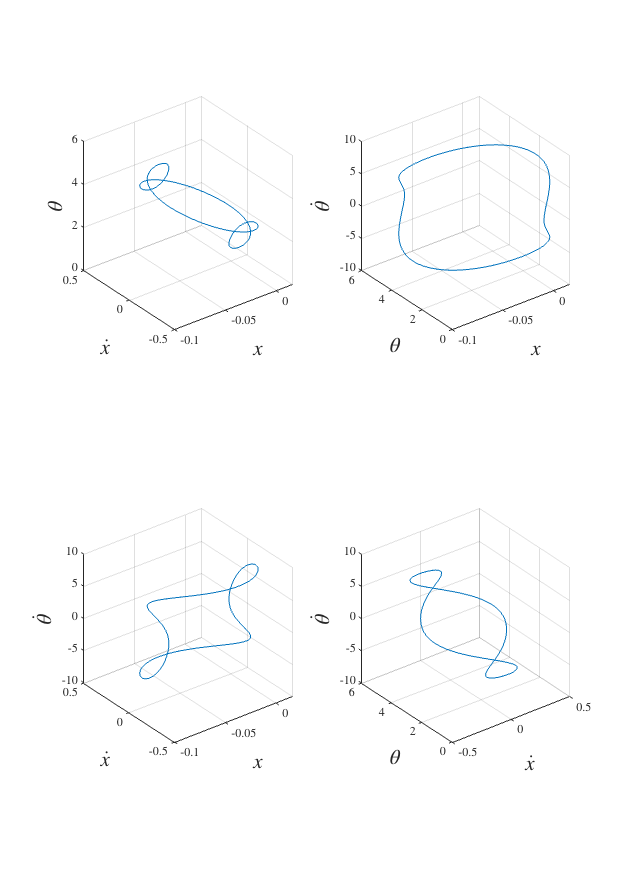

studio_piano_fasi_3D = figure;

set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);

subplot(2,2,1);
plot3(x(:,3),x(:,4),x(:,1));
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
xlabel('$x$','Interpreter','latex','FontSize',14);
ylabel('$\dot{x}$','Interpreter','latex','FontSize',14);
zlabel('$\theta$','Interpreter','latex','FontSize',14);
axis square;
grid on;

subplot(2,2,2);
plot3(x(:,3),x(:,1),x(:,2));
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
xlabel('$x$','Interpreter','latex','FontSize',14);
ylabel('$\theta$','Interpreter','latex','FontSize',14);
zlabel('$\dot{\theta}$','Interpreter','latex','FontSize',14);
axis square;
grid on;

subplot(2,2,3);
plot3(x(:,3),x(:,4),x(:,2));
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
xlabel('$x$','Interpreter','latex','FontSize',14);
ylabel('$\dot{x}$','Interpreter','latex','FontSize',14);
zlabel('$\dot{\theta}$','Interpreter','latex','FontSize',14);
axis square;
grid on;

subplot(2,2,4);
plot3(x(:,4),x(:,1),x(:,2));
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
xlabel('$\dot{x}$','Interpreter','latex','FontSize',14);
ylabel('$\theta$','Interpreter','latex','FontSize',14);
zlabel('$\dot{\theta}$','Interpreter','latex','FontSize',14);
axis square;
grid on;

%exportgraphics(studio_piano_fasi_3D,'studio_piano_fasi_3D.eps','Resolution',300);

Se cambiamo leggermente i  valori iniziali:

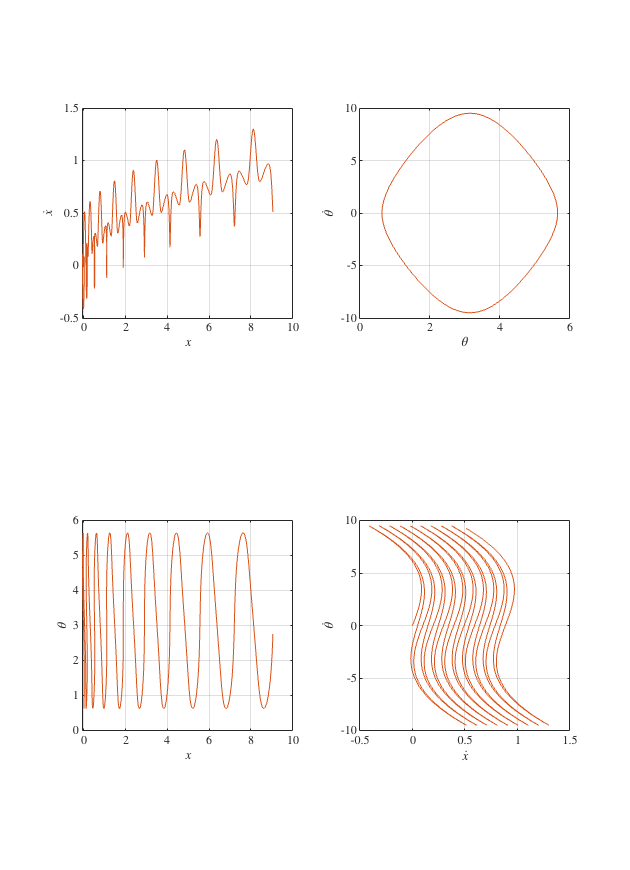

dt = [0 20];
m = 0.1;%kg
M = 1;%kg
l = 0.5;%m
F = 0.05;%N
x0 =[pi/5,0,0,0];
[t,x] = ode45(@(t,x)Inv_pend(x,t,m,M,l,F),dt,x0,opts);
studio_piano_fasi_2D = figure;
grid on;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);


subplot(2,2,1);
plot(x(:,3),x(:,4),'Color',[0.8500, 0.3250, 0.0980]); %x xpunto
xlabel('$x$','Interpreter','latex','FontSize',14);
ylabel('$\dot{x}$','Interpreter','latex','FontSize',14);
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
axis square;
grid on;

subplot(2,2,2);
plot(x(:,1),x(:,2),'Color',[0.8500, 0.3250, 0.0980]); %theta thetapunto 
xlabel('$\theta$','Interpreter','latex','FontSize',14);
ylabel('$\dot{\theta}$','Interpreter','latex','FontSize',14);
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
axis square;
grid on;

subplot(2,2,3);
plot(x(:,3),x(:,1),'Color',[0.8500, 0.3250, 0.0980]);%x theta
xlabel('$x$','Interpreter','latex','FontSize',14);
ylabel('$\theta$','Interpreter','latex','FontSize',14);
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
axis square;
grid on;

subplot(2,2,4);
plot(x(:,4),x(:,2),'Color',[0.8500, 0.3250, 0.0980]); % xpunto thetapunto 
xlabel('$\dot{x}$','Interpreter','latex','FontSize',14);
ylabel('$\dot{\theta}$','Interpreter','latex','FontSize',14);
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
axis square;
grid on;

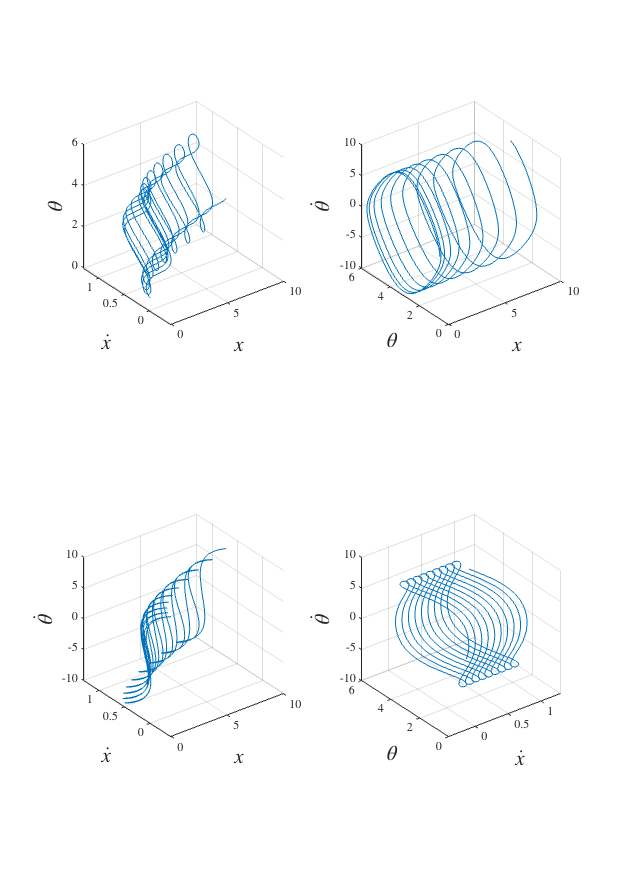

%exportgraphics(studio_piano_fasi_2D,'studio_piano_fasi_2D_var.eps','Resolution',300);

studio_piano_fasi_3D = figure;

set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);

subplot(2,2,1);
plot3(x(:,3),x(:,4),x(:,1));
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
xlabel('$x$','Interpreter','latex','FontSize',14);
ylabel('$\dot{x}$','Interpreter','latex','FontSize',14);
zlabel('$\theta$','Interpreter','latex','FontSize',14);
axis square;
grid on;

subplot(2,2,2);
plot3(x(:,3),x(:,1),x(:,2));
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
xlabel('$x$','Interpreter','latex','FontSize',14);
ylabel('$\theta$','Interpreter','latex','FontSize',14);
zlabel('$\dot{\theta}$','Interpreter','latex','FontSize',14);
axis square;
grid on;

subplot(2,2,3);
plot3(x(:,3),x(:,4),x(:,2));
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
xlabel('$x$','Interpreter','latex','FontSize',14);
ylabel('$\dot{x}$','Interpreter','latex','FontSize',14);
zlabel('$\dot{\theta}$','Interpreter','latex','FontSize',14);
axis square;
grid on;

subplot(2,2,4);
plot3(x(:,4),x(:,1),x(:,2));
set(gca,'TickLabelInterpreter', 'latex','fontsize',8);
xlabel('$\dot{x}$','Interpreter','latex','FontSize',14);
ylabel('$\theta$','Interpreter','latex','FontSize',14);
zlabel('$\dot{\theta}$','Interpreter','latex','FontSize',14);
axis square;
grid on;

%exportgraphics(studio_piano_fasi_3D,'studio_piano_fasi_3D_var.eps','Resolution',300);